## **Verify the solution of the differential equation:**

        
$$\frac{\mathrm{dy}}{\mathrm{dt}}=\sin \left(3t\right)-2y\;\;\;\;\;,y\left(0\right)=\frac{6}{5}$$


This is a first order inhomogeneous differential equation which can be rewritten as:  

         
$$\frac{\mathrm{dy}}{\mathrm{dt}}+2y=\sin \left(3t\right)$$
 

### The solution to the equation is therfore given by: $y=y_h +y_p$

Where $y_h$ denotes the solution to the same homogenus equation and $y_p$ denotes the particular solution.

#### To find $y_h$ we solve the following homogenus differential equation:

        
$$\frac{\mathrm{dy}}{\mathrm{dt}}+2y=0$$


Plugging in the formula or trivialy solving this we get that: 

        
$$y_h ={\mathrm{Ce}}^{-2t}$$


#### To find $y_p$ we solve for the constants in the assumed solution:

The solution can be assumed to take the form of:

        
$$y_p =\mathrm{Asin}\left(3t\right)+\mathrm{Bcos}\left(3t\right)\;\;\;\;\mathrm{then}:$$


        
$$\frac{{\mathrm{dy}}_p }{\mathrm{dt}}=3\mathrm{Acos}\left(3t\right)-3\mathrm{Bsin}\left(3t\right)$$


Plugging into the original differential equation we get:

        
$$3\mathrm{Acos}\left(3t\right)-3\mathrm{Bsin}\left(3t\right)+2\left(\mathrm{Asin}\left(3t\right)+\mathrm{Bcos}\left(3t\right)\right)=\sin \left(3t\right)$$


        
$$\Leftrightarrow \left(2B+3A\right)\cos \left(3t\right)+\left(2A-3B\right)\sin \left(3t\right)=\sin \left(3t\right)$$


Denote the following:

        
$$\mathrm{VL}=\left(2B+3A\right)\cos \left(3t\right)+\left(2A-3B\right)\sin \left(3t\right)$$


        
$$\mathrm{HL}=\sin \left(3t\right)$$


In order for $\mathrm{VL}=\mathrm{HL}$ we must find the constants $A,\;B$ such that the following system of equations is satisfied:

        
$$\left\lbrace \begin{array}{ll}
3A+2B=0 & \\
2A-3B=1 & 
\end{array}\right.$$


The solutions are: $A=\frac{2}{13}\;\;\;\;,B=-\frac{3}{13}$

We see that this is true with the following code:

format rational
A = [3, 2; 2, -3];
b = [0 1]';

constants = A\b

constants =        2/13    
      -3/13    


Then we can plug in the constants in the equation for $y_p$:

        
$$y_p =\frac{2}{13}\sin \left(3t\right)-\frac{3}{13}\cos \left(3t\right)$$


#### The general solution can then be written as:

        
$$y=y_h +y_p ={\mathrm{Ce}}^{-2t} +\frac{2}{13}\sin \left(3t\right)-\frac{3}{13}\cos \left(3t\right)\;$$


Plugging in $y\left(0\right)=\frac{6}{5}$ we can solve for the constant $C$:

        
$${\mathrm{Ce}}^{-2\cdot 0} +\frac{2}{13}\sin \left(3\cdot 0\right)-\frac{3}{13}\cos \left(3\cdot 0\right)\;=\frac{6}{5}$$


        
$$\Leftrightarrow C-\frac{3}{13}=\frac{6}{5}$$


        
$$\Leftrightarrow C=\frac{6}{5}+\frac{3}{13}$$


        
$$\Leftrightarrow C=\frac{93}{65}$$


Therefor the solution to the IVP is:

        
$$y=\frac{93}{65}e^{-2t} +\frac{2}{13}\sin \left(3t\right)-\frac{3}{13}\cos \left(3t\right)\;$$


Visualized here over $t\in \left\lbrack 0,8\right\rbrack$:

x_plot = 0:0.1:8;
y_plot = (93/65)*exp(-2*x_plot)+(2/13)*sin(3*x_plot)-(3/13)*cos(3*x_plot);     

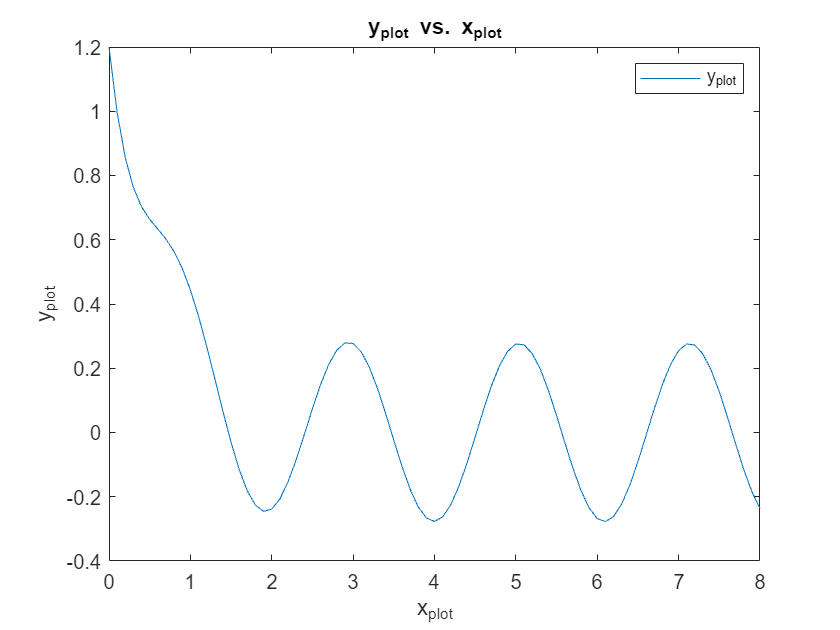

% Create plot of selected data
h = plot(x_plot,y_plot,"DisplayName","y_plot");

% Add xlabel, ylabel, title, and legend
xlabel("x_plot")
ylabel("y_plot")
title("y_plot vs. x_plot")
legend